# 直交基底、直交行列、Gram-Schmidtの直行化法

## 正規直交

ベクトル$q_1 \cdots q_n$は


$$q_i^T q_j \left\lbrace \begin{array}{c}
0 & i\ne j\left(\mathrm{直交ベクトル}\right)\\
1 & i=j\left(\mathrm{単位ベクトル}:\left\|q_i \right\|=1\right)
\end{array}\right.$$


## 射影と最小2乗：正規直交の場合

もし$A$の列が正規直交ならば


$$A^T A=\left\lbrack \begin{array}{c}
\cdots  & a_1^T  & \cdots \\
\cdots  & a_2^T  & \cdots \\
\cdots  & \vdots  & \cdots \\
\cdots  & a_n^T  & \cdots 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\vdots  & \vdots  & \vdots  & \vdots \\
a_1  & a_2  & \cdots  & a_n \\
\vdots  & \vdots  & \vdots  & \vdots 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1 & 0 & \cdots  & 0\\
0 & 1 & \cdots  & 0\\
\vdots  & \vdots  & \ddots  & \vdots \\
0 & 0 & \cdots  & 1
\end{array}\right\rbrack =I$$


これにより、射影行列は


$$P={\mathrm{AA}}^T ,\text{   }\overline{x} =A^T b$$


となる

## 3.3.1

A = [1,-2;1,-1;1,1;1,2]

A =        1             -2       
       1             -1       
       1              1       
       1              2       


b = [-4;-3;-1;0]

b =       -4       
      -3       
      -1       
       0       


dot(A(:,1),A(:,2))

ans =        0       



$$\begin{array}{l}
C=\frac{1}{2}c\\
c=2C\\
D=\frac{1}{\sqrt{10}}d\\
d=\sqrt{10}D
\end{array}$$


A2 = [A(:,1)*(1/4),A(:,2)*(1/10)]

A2 =        1/4           -1/5     
       1/4           -1/10    
       1/4            1/10    
       1/4            1/5     


x=A2'*b

x =       -2       
       1       



$$y=-2+t$$


t = [-2,-1,1,2]

t =       -2             -1              1              2       


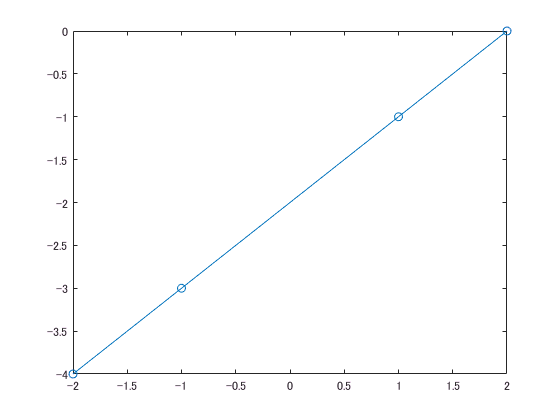

plot(t,-2+t,'-o')

A * x

ans =       -4       
      -3       
      -1       
       0       


norm(A*x-b)

ans =        0       


## 3.3.2

b = [0;3;0]

b =        0       
       3       
       0       


a1 = [2/3;2/3;-1/3]

a1 =        2/3     
       2/3     
      -1/3     


a2 = [-1/3;2/3;2/3]

a2 =       -1/3     
       2/3     
       2/3     


a1 * a1'*b

ans =        4/3     
       4/3     
      -2/3     


a2 * a2' *b

ans =       -2/3     
       4/3     
       4/3     


A = [a1,a2]

A =        2/3           -1/3     
       2/3            2/3     
      -1/3            2/3     


A * A' * b

ans =        2/3     
       8/3     
       2/3     


## 3.3.3

a3 = [2/3;-1/3;2/3]

a3 =        2/3     
      -1/3     
       2/3     


a3 * a3' * b

ans =       -2/3     
       1/3     
      -2/3     


A = [a1,a2,a3]

A =        2/3           -1/3            2/3     
       2/3            2/3           -1/3     
      -1/3            2/3            2/3     


a1 * a1'*b+a2 * a2' *b + a3 * a3' * b

ans =        0       
       3       
       0       


## 直交行列

正規直交の列を持つ正方行列


$$\begin{array}{l}
Q^{T\text{ }} Q=I\\
{\mathrm{QQ}}^T =I\\
Q^T =Q^{-1} 
\end{array}$$


## 例1


$$\begin{array}{l}
Q=\left\lbrack \begin{array}{c}
\mathrm{cos}\theta  & -\mathrm{sin}\theta \\
\mathrm{sin}\theta  & \mathrm{cos}\theta 
\end{array}\right\rbrack \\
Q^T =Q^{-1} =\left\lbrack \begin{array}{c}
\mathrm{cos}\theta  & \mathrm{sin}\theta \\
-\mathrm{sin}\theta  & \mathrm{cos}\theta 
\end{array}\right\rbrack 
\end{array}$$


## 例2

交換行列$P$は直交行列


$$\begin{array}{l}
P=\left\lbrack \begin{array}{c}
0 & 1\\
1 & 0
\end{array}\right\rbrack \\
P^{-1} =P^T =\left\lbrack \begin{array}{c}
0 & 1\\
1 & 0
\end{array}\right\rbrack 
\end{array}$$



$$\begin{array}{l}
P=\left\lbrack \begin{array}{c}
0 & 1 & 0\\
0 & 0 & 1\\
1 & 0 & 0
\end{array}\right\rbrack \\
P^{-1} =P^T =\left\lbrack \begin{array}{c}
0 & 0 & 1\\
1 & 0 & 0\\
0 & 1 & 0
\end{array}\right\rbrack 
\end{array}$$


## 直行行列の最も重要な性質

直行行列による積は長さを保存する


$$\left\|\mathit{Qx}\right\|=\left\|x\right\|$$


また、内積も保存される


$${\left(\mathit{Qx}\right)}^T \left(\mathit{Qy}\right)=x^T y$$


## 3.3.4


$${\left(Q_1 Q_2 \right)}^T Q_1 Q_2 =Q_2^T Q_1^T Q_1 Q_2 =Q_2^T {\mathit{IQ}}_2 =Q_2^T Q_2 =I$$



$$Q_1 Q_2 {\left(Q_1 Q_2 \right)}^T =Q_1 Q_2 Q_2^T Q_1^T =Q_1 Q^T =I$$



$${\left(Q_1 Q_2 \right)}^T =Q_2^T Q_1^T =Q_2^{−1} Q_1^{−1} ={\left(Q_1 Q_2 \right)}^{−1}$$


## 3.3.5


$$Q^T ={\left(I−2{\mathit{uu}}^T \right)}^T =I−2{\left({\mathit{uu}}^T \right)}^T =I−2{\mathit{uu}}^T$$



$${\mathit{QQ}}^T =\left(I−2{\mathit{uu}}^T \right)\left(I−2{\mathit{uu}}^T \right)=I−4{\mathit{uu}}^T +4{\mathit{uu}}^T {\mathit{uu}}^T =I$$


clear
u = [1/sqrt(3);1/sqrt(3);1/sqrt(3)]

u =      780/1351  
     780/1351  
     780/1351  


Q = eye(3)-2*u*u'

Q =        1/3           -2/3           -2/3     
      -2/3            1/3           -2/3     
      -2/3           -2/3            1/3     


## 3.3.6

clear
A = [1/sqrt(3),1/sqrt(3),1/sqrt(3);1/sqrt(2),0,-1/sqrt(2)]

A =      780/1351       780/1351       780/1351  
     985/1393         0           -985/1393  


E21 = eye(2);
E21(2,1) = -sqrt(3)/sqrt(2)

E21 =        1              0       
   -1079/881          1       


U = E21 * A

U =      780/1351       780/1351       780/1351  
       *           -985/1393     -1393/985   


E12 = eye(2)

E12 =        1              0       
       0              1       


E12(1,2) = sqrt(2)/sqrt(3)

E12 =        1            881/1079  
       0              1       


U = E12 * U

U =      780/1351         0           -780/1351  
       *           -985/1393     -1393/985   



$$\begin{array}{l}
x=\left\lbrack \begin{array}{c}
a\\
b\\
c
\end{array}\right\rbrack \\
\frac{1}{\sqrt{3}}a=\frac{1}{\sqrt{3}}c\\
a=c\\
-\frac{1}{\sqrt{2}}b=\sqrt{2}c\\
b=-2c
\end{array}$$



$$x=\left\lbrack \begin{array}{c}
a\\
-2a\\
a
\end{array}\right\rbrack =\pm \frac{1}{\sqrt{6}}\left\lbrack \begin{array}{c}
1\\
-2\\
1
\end{array}\right\rbrack$$


## 3.3.7

ベクトルが正規直行の場合


$$q_i^T q_j \left\lbrace \begin{array}{c}
0 & i\ne j\left(\text{直交ベクトル}\right)\\
1 & i=j\left(\text{単位ベクトル}:\left\|q_i \right\|=1\right)
\end{array}\right.$$


より、


$$\begin{array}{l}
{\mathit{vv}}^T =\left(q_1 x_1 +\cdots +q_n x_n \right){\left(q_1 x_1 +\cdots +q_n x_n \right)}^T \\
=x_1^2 +\cdots +x_n^2 
\end{array}$$


## 3.3.8

clear
Q = [1/2,1/2,1/2,1/2;
    1/2,1/2,-1/2,-1/2;
    1/2,-1/2,-1/2,1/2;
    1/2,-1/2,1/2,-1/2;]

Q =        1/2            1/2            1/2            1/2     
       1/2            1/2           -1/2           -1/2     
       1/2           -1/2           -1/2            1/2     
       1/2           -1/2            1/2           -1/2     


Q*Q'

ans =        1              0              0              0       
       0              1              0              0       
       0              0              1              0       
       0              0              0              1       


Q'*Q

ans =        1              0              0              0       
       0              1              0              0       
       0              0              1              0       
       0              0              0              1       


Q'

ans =        1/2            1/2            1/2            1/2     
       1/2            1/2           -1/2           -1/2     
       1/2           -1/2           -1/2            1/2     
       1/2           -1/2            1/2           -1/2     


Q^-1

ans =        1/2            1/2            1/2            1/2     
       1/2            1/2           -1/2           -1/2     
       1/2           -1/2           -1/2            1/2     
       1/2           -1/2            1/2           -1/2     


直交行列

## Gram-Schmidtの直交化法

列を正規直交にする方法

任意の線形独立なベクトルの集合$a_{1,} \cdots ,a_n$をGram-Schmidtの過程によって直交ベクトルの集合へ変換


$$\begin{array}{l}
v_1 =a_1 \\
v_i =a_i −\frac{v_1^T a_i }{v_1^T v_1 }v_1 −\cdots −\frac{v_{i−1}^T a_i }{v_{i−1}^T v_{i−1} }v_{i−1} \\
q_i =\frac{v_i }{\left\|v_i \right\|}は正規直交
\end{array}$$


## 例


$$a_1 =\left\lbrack \begin{array}{c}
1\\
1\\
0
\end{array}\right\rbrack ,a_2 =\left\lbrack \begin{array}{c}
1\\
0\\
1
\end{array}\right\rbrack ,a_3 =\left\lbrack \begin{array}{c}
0\\
1\\
1
\end{array}\right\rbrack$$



$$\begin{array}{l}
v_1 =a_1 \\
v_2 =a_2 −\frac{1}{2}v_1 \\
v_3 =a_3 −\frac{1}{2}v_1 −\frac{1}{3}v_2 
\end{array}$$



$$\begin{array}{l}
q_1 =\frac{v_1 }{\left\|v_1 \right\|}=\sqrt{\frac{1}{2}}\left\lbrack \begin{array}{c}
1\\
1\\
0
\end{array}\right\rbrack \\
q_2 =\frac{v_2 }{\left\|v_2 \right\|}=\sqrt{\frac{2}{3}}\left\lbrack \begin{array}{c}
\frac{1}{2}\\
−\frac{1}{2}\\
1
\end{array}\right\rbrack \\
q_3 =\frac{v_3 }{\left\|v_3 \right\|}=\sqrt{\frac{3}{4}}\left\lbrack \begin{array}{c}
−\frac{2}{3}\\
\frac{2}{3}\\
\frac{2}{3}
\end{array}\right\rbrack 
\end{array}$$



$$\begin{array}{l}
a_1 =v_1 \\
a_2 =\frac{1}{2}v_1 +v_2 \\
a_3 =\frac{1}{3}v_1 +\frac{1}{2}v_2 +v_3 
\end{array}$$


若しくは


$$\begin{array}{l}
a_1 =\sqrt{2}q_1 \\
a_2 =\sqrt{\frac{1}{2}}q_1 +\sqrt{\frac{3}{2}}q_2 \\
a_3 =\sqrt{\frac{1}{2}}q_1 +\sqrt{\frac{1}{6}}q_2 +\sqrt{\frac{4}{3}}q_3 
\end{array}$$


以上より


$$\left\lbrack \begin{array}{c}
a_1  & a_2  & a_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
q_1  & q_2  & q_3 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\sqrt{2} & \sqrt{\frac{1}{2}} & \sqrt{\frac{1}{2}}\\
0 & \sqrt{\frac{3}{2}} & \sqrt{\frac{1}{6}}\\
0 & 0 & \sqrt{\frac{4}{3}}
\end{array}\right\rbrack$$



$$A=\mathit{QR}$$


## 3.3.9

a1 = [0;0;1]

a1 =        0       
       0       
       1       


a2 = [0;1;1]

a2 =        0       
       1       
       1       


a3 = [1;1;1]

a3 =        1       
       1       
       1       


v1 = a1

v1 =        0       
       0       
       1       


v2 = a2 - (a2' * v1)/(v1' * v1)*v1

v2 =        0       
       1       
       0       


v3 = a3 - (a3' * v1) / (v1' * v1)*v1 - (a3' * v2)/(v2' * v2)*v2

v3 =        1       
       0       
       0       


q1 = v1 / norm(v1)

q1 =        0       
       0       
       1       


q2 = v2/norm(v2)

q2 =        0       
       1       
       0       


q3 = v3/norm(v3)

q3 =        1       
       0       
       0       


A = [a1,a2,a3]

A =        0              0              1       
       0              1              1       
       1              1              1       


Q = [q1,q2,q3]

Q =        0              0              1       
       0              1              0       
       1              0              0       


R = [1,1,1;0,1,1;0,0,1]

R =        1              1              1       
       0              1              1       
       0              0              1       


Q * R

ans =        0              0              1       
       0              1              1       
       1              1              1       


## 3.3.10

clear
A = [3,0;4,5]

A =        3              0       
       4              5       


a1 = [3;4]

a1 =        3       
       4       


a2 = [0;5]

a2 =        0       
       5       


v1 = a1

v1 =        3       
       4       


v2 = a2 - (a2' * v1)/(v1' * v1)*v1

v2 =      -12/5     
       9/5     


q1 = v1 / norm(v1)

q1 =        3/5     
       4/5     


q2 = v2 / norm(v2)

q2 =       -4/5     
       3/5     


Q = [q1,q2]

Q =        3/5           -4/5     
       4/5            3/5     


R = [5,4;0,3]

R =        5              4       
       0              3       


Q * R

ans =        3              *       
       4              5       


## 3.3.11

clear
a1 = [1;2;2]

a1 =        1       
       2       
       2       


a2 = [1;3;1]

a2 =        1       
       3       
       1       


v1 = a1

v1 =        1       
       2       
       2       


v2 = a2 - (a2' * v1)/(v1' * v1)*v1

v2 =        0       
       1       
      -1       


q1 = v1 / norm(v1)

q1 =        1/3     
       2/3     
       2/3     


q2 = v2 / norm(v2)

q2 =        0       
     985/1393  
    -985/1393  


Q = [q1,q2]

Q =        1/3            0       
       2/3          985/1393  
       2/3         -985/1393  


R = [3,3;0,sqrt(2)]

R =        3              3       
       0           1393/985   


Q * R

ans =        1              1       
       2              3       
       2              1       



$$A=m\times n$$


ならば


$$\begin{array}{l}
Q=m\times n\\
R=n\times n
\end{array}$$


## 3.3.12

clear
a1 = [1;2;2]

a1 =        1       
       2       
       2       


a2 = [1;3;1]

a2 =        1       
       3       
       1       


b = [1;1;1]

b =        1       
       1       
       1       


A = [a1,a2]

A =        1              1       
       2              3       
       2              1       


v1 = a1

v1 =        1       
       2       
       2       


v2 = a2 - (a2' * v1)/(v1' * v1)*v1

v2 =        0       
       1       
      -1       


q1 = v1 / norm(v1)

q1 =        1/3     
       2/3     
       2/3     


q2 = v2 / norm(v2)

q2 =        0       
     985/1393  
    -985/1393  


Q = [q1,q2]

Q =        1/3            0       
       2/3          985/1393  
       2/3         -985/1393  


R = [3,3;0,sqrt(2)]

R =        3              3       
       0           1393/985   


R^-1 * Q' * b

ans =        5/9     
       0       


## 3.3.13


$$\begin{array}{l}
P={\mathit{QR}\left(R^T Q^T \mathit{QR}\right)}^{−1} R^T Q^T \\
={\mathit{QRR}}^{−1} {\left(R^T \right)}^{−1} R^T Q^T \\
={\mathit{QQ}}^T 
\end{array}$$


## 3.3.14


$$v_2^T \left(c-\frac{v_1^T c}{v_1^T v_1 }v_1 \right)=v_2^T c-\frac{v_1^T c}{v_1^T v_1 }{v_2^T v}_1 =v_2^T$$


## 関数空間とFurier級数

**Hilbert空間**

ベクトル$\left(v_1 ,v_2 \cdots \right)$はその長さ$\left\|v\right\|$が有限であるとき、かつその時に限り、無限次元の「ヒルベルト空間」にある

**関数の区間の長さ**

例えば、区間$0\le x\le 2\pi$の関数$f\left(x\right)$の長さを求める場合


$${\left\|f\right\|}^2 =\int_0^{2\pi } {\left(f\left(x\right)\right)}^2 \mathit{dx}$$


**Furier級数**


$$y\left(x\right)=a_0 +a_1 \mathrm{cos}\left(x\right)+b_1 \mathrm{sin}\left(x\right)+a_2 \mathrm{cos}\left(2x\right)+\cdots$$


このとき、係数$b_1$を求めるには、両辺に$\mathrm{sin}\left(x\right)$をかけて、0から$2\pi$まで積分する


$$\int_0^{2\pi } y\left(x\right)\mathrm{sin}\left(x\right)\mathit{dx}=a_0 \int_0^{2\pi } \mathrm{sin}\left(x\right)\mathit{dx}+a_1 \int_0^{2\pi } \mathrm{cos}\left(x\right)\mathrm{sin}\left(x\right)\mathit{dx}+b_1 \int_0^{2\pi } {\left(\mathrm{sin}\left(x\right)\right)}^2 \mathit{dx}+\cdots$$


sinとcosは互いに直交なので、sincosは0そのほかも$b_1$の値以外はすべて積分すると0になるので


$$f\left(x\right)=\mathrm{sin}\left(x\right)$$



$$b_1 =\frac{\int_0^{2\pi } y\left(x\right)\mathrm{sin}\left(x\right)\mathit{dx}}{\int_0^{2\pi } {\left(\mathrm{sin}\left(x\right)\right)}^2 \mathit{dx}}=\frac{y^T f}{f^T f}$$


もしくは


$$b_1 \mathrm{sin}\left(x\right)=\frac{y^T f}{f^T f}f$$


## 3.3.15


$${\left\|v\right\|}^2 =\frac{1}{2}+\frac{1}{4}+\frac{1}{8}+\cdots =1$$



$$\begin{array}{l}
\int_0^1 e^{2x} \mathit{dx}={\left\lbrack \frac{e^{2x} }{2}\right\rbrack }_0^1 =\frac{1}{2}\left(e^2 -1\right)\\
\int_0^1 e^x e^{-x} \mathrm{dx}=1
\end{array}$$


## 3.3.16


$$b_1 =\frac{\int_0^{2\pi } y\left(x\right)\mathrm{sin}\left(x\right)\mathit{dx}}{\int_0^{2\pi } {\left(\mathrm{sin}\left(x\right)\right)}^2 \mathit{dx}}$$


## 3.3.17


$$a_0 =\int_0^{2\pi } y=\frac{1}{2}$$



$$a_1 =\frac{\int_0^{\pi } y\text{ }\mathrm{cos}\left(x\right)\mathit{dx}+\int_{\pi \text{ }}^{2\pi } y\text{ }\mathrm{cos}\left(x\right)\mathit{dx}}{\int_0^{\pi } {\left(\mathrm{cos}\left(x\right)\right)}^2 \mathit{dx}+\int_{\pi }^{2\pi } {\left(\mathrm{cos}\left(x\right)\right)}^2 \mathit{dx}}=0$$



$$b_1 =\frac{\int_0^{\pi } \mathrm{ysin}\left(x\right)\mathit{dx}+\int_{\pi \text{ }}^{2\pi } y\text{ }\mathrm{sin}\left(x\right)\mathit{dx}}{\int_0^{\pi } {\left(\mathrm{sin}\left(x\right)\right)}^2 \mathit{dx}+\int_{\pi }^{2\pi } {\left(\mathrm{sin}\left(x\right)\right)}^2 \mathit{dx}}=\frac{2}{\pi }$$


## 3.3.18


$$v_4 =x^3 -\frac{\int_{-1}^1 x^3 \mathit{xdx}=\frac{2}{5}}{\int_{-1}^1 \mathit{xxdx}=\frac{2}{3}}x=x^3 -\frac{3}{5}x$$


## 3.3.19


$$y=\frac{x^T 1}{1^T 1}+\frac{x^{2T} x}{x^T x}x=\frac{\left(\frac{2}{3}\right)}{2}+0=\frac{1}{3}$$
